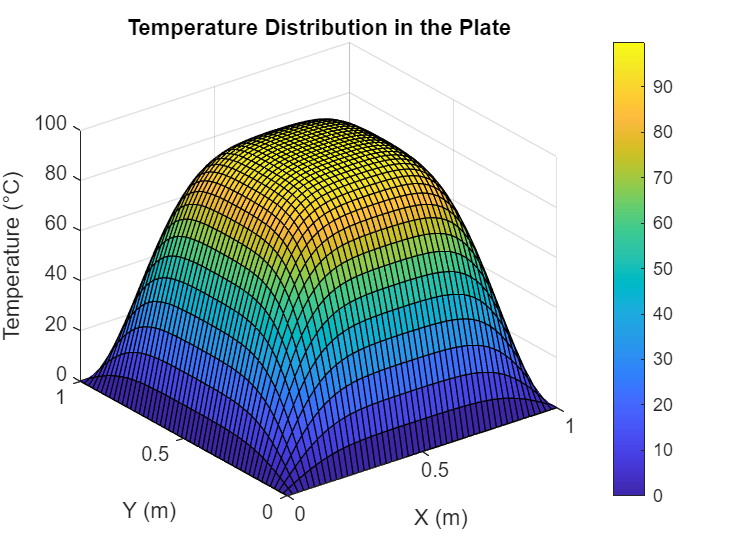

L = 1;                % Length of the plate (m)
nx = 50;              % Number of grid points in x-direction
ny = 50;              % Number of grid points in y-direction
dx = L / (nx - 1);    % Grid spacing in x-direction
dy = L / (ny - 1);    % Grid spacing in y-direction
alpha = 0.01;         % Thermal diffusivity (m^2/s)
dt = 0.001;           % Time step (s)
nt = 1000;            % Number of time steps
T_initial = 100;      % Initial temperature (Celsius)

%  temperature field
T = T_initial * ones(nx, ny);

% Boundary conditions
T(:, 1) = 0;          % Left edge (Dirichlet BC)
T(:, end) = 0;        % Right edge (Dirichlet BC)
T(1, :) = 0;          % Bottom edge (Dirichlet BC)
T(end, :) = 0;        % Top edge (Dirichlet BC)

% Time-stepping loop
for t = 1:nt
    T_old = T;
    
    % Update interior points using finite differences
    for i = 2:nx-1
        for j = 2:ny-1
            Txx = (T_old(i+1, j) - 2*T_old(i, j) + T_old(i-1, j)) / dx^2;
            Tyy = (T_old(i, j+1) - 2*T_old(i, j) + T_old(i, j-1)) / dy^2;
            T(i, j) = T_old(i, j) + alpha * dt * (Txx + Tyy);
        end
    end
    
    % Apply boundary conditions again (to ensure they are enforced)
    T(:, 1) = 0;          % Left edge
    T(:, end) = 0;        % Right edge
    T(1, :) = 0;          % Bottom edge
    T(end, :) = 0;        % Top edge
end

% Plot the final temperature distribution
figure;
surf(linspace(0, L, nx), linspace(0, L, ny), T);
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Temperature (°C)');
title('Temperature Distribution in the Plate');
colorbar;

% Interactive Heat Transfer Simulation in a Metal Plate

% Create a figure for the simulation
fig = figure('Name', 'Interactive Heat Transfer Simulation', 'NumberTitle', 'off', ...
    'Position', [100, 100, 800, 600]);

% Add sliders for interaction
uicontrol('Style', 'text', 'String', 'Thermal Diffusivity (alpha):', ...
    'Position', [50, 550, 150, 20]);
alpha_slider = uicontrol('Style', 'slider', 'Min', 0.001, 'Max', 0.1, 'Value', 0.01, ...
    'Position', [200, 550, 200, 20], 'Callback', @update_alpha);

uicontrol('Style', 'text', 'String', 'Time Step (dt):', ...
    'Position', [50, 520, 150, 20]);
dt_slider = uicontrol('Style', 'slider', 'Min', 0.0001, 'Max', 0.01, 'Value', 0.001, ...
    'Position', [200, 520, 200, 20], 'Callback', @update_dt);

uicontrol('Style', 'text', 'String', 'Simulation Speed:', ...
    'Position', [50, 490, 150, 20]);
speed_slider = uicontrol('Style', 'slider', 'Min', 0.1, 'Max', 2, 'Value', 1, ...
    'Position', [200, 490, 200, 20], 'Callback', @update_speed);

% Axes for the temperature plot
ax = axes('Parent', fig, 'Position', [0.3, 0.1, 0.6, 0.7]);

% Initialize variables
L = 1;                % Length of the plate (m)
nx = 50;              % Number of grid points in x-direction
ny = 50;              % Number of grid points in y-direction
dx = L / (nx - 1);    % Grid spacing in x-direction
dy = L / (ny - 1);    % Grid spacing in y-direction
alpha = 0.01;         % Thermal diffusivity (m^2/s)
dt = 0.001;           % Time step (s)
speed_factor = 1;     % Speed multiplier
T_initial = 100;      % Initial temperature (Celsius)

% Initialize temperature field
T = T_initial * ones(nx, ny);

% Boundary conditions
T(:, 1) = 0;          % Left edge (Dirichlet BC)
T(:, end) = 0;        % Right edge (Dirichlet BC)
T(1, :) = 0;          % Bottom edge (Dirichlet BC)
T(end, :) = 0;        % Top edge (Dirichlet BC)

% Plot initial temperature distribution
h_surf = surf(linspace(0, L, nx), linspace(0, L, ny), T, 'EdgeColor', 'none');
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Temperature (°C)');
title('Interactive Temperature Distribution in the Plate');
colorbar;

% Callback functions for sliders
function update_alpha(~, ~)
    alpha = alpha_slider.Value;
end

function update_dt(~, ~)
    dt = dt_slider.Value;
end

function update_speed(~, ~)
    speed_factor = speed_slider.Value;
end

% Real-time simulation loop
while ishandle(fig)
    T_old = T;
    
    % Update interior points using finite differences
    for i = 2:nx-1
        for j = 2:ny-1
            Txx = (T_old(i+1, j) - 2*T_old(i, j) + T_old(i-1, j)) / dx^2;
            Tyy = (T_old(i, j+1) - 2*T_old(i, j) + T_old(i, j-1)) / dy^2;
            T(i, j) = T_old(i, j) + alpha * dt * (Txx + Tyy);
        end
    end
    
    % Apply boundary conditions again
    T(:, 1) = 0;          % Left edge
    T(:, end) = 0;        % Right edge
    T(1, :) = 0;          % Bottom edge
    T(end, :) = 0;        % Top edge
    
    % Update the surface plot
    set(h_surf, 'ZData', T);
    drawnow limitrate;
    
    % Control simulation speed
    pause(dt / speed_factor);
end